clear all;

## **Signal creation**

use_audio = true;
export_img = false;

if use_audio
    [signal_1_stereo,~] = audioread('super-mario_kurz.mp3');       % Sampling signal 1
    [signal_2_stereo, fs] = audioread('fake-news.mp3');            % Sampling signal 2
    
    signal_1=signal_1_stereo(:,1)';
    signal_2=signal_2_stereo(:,1)';
    
    % Generate new log2() signal length for FFT
    N = length(signal_1)
    N_log2 = 2^floor(log2(N));

    signal_1 = signal_1(1:N_log2);
    signal_2 = signal_2(1:N_log2);

    N = length(signal_1)
    N_log2 = log2(N)
    N_half = N/2;
    t = (0:N-1)/fs;                                                 % Timeaxis
    ts = 1/fs; 

    cutoff_f = 5000
else 
    fs = 1000; 
    ts = 1/fs;
    duration = 2^10/1000;  
    t = 0:1/fs:duration-ts;
    freq_sinus = 100;
    freq_rechteck = 150;
    signal_1 = square(2 * pi * freq_sinus * t);
    signal_2 = square(2 * pi * freq_rechteck * t);
    N = length(signal_1);
    cutoff_f = 490
end

N = 121584

N = 65536

N_log2 = 16

cutoff_f = 5000

#### Plot the initial signal's

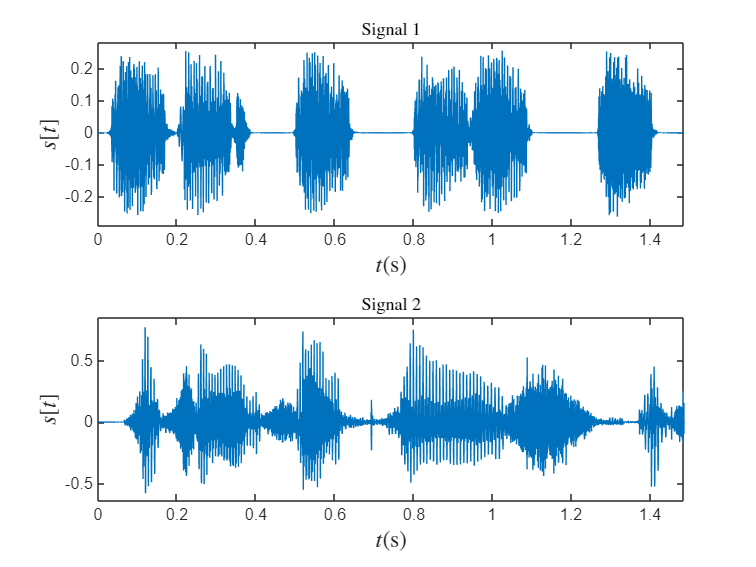

figure()
tiledlayout(2,1);
nexttile
plot(t,signal_1)
title('Signal 1','Interpreter','Latex')
xlabel('$t$(s)','Interpreter','Latex', 'FontSize', 13)
ylabel('$s[t]$', 'Interpreter', 'latex', 'FontSize', 13);
xlim([0 max(t)])
ylim([min(signal_1)*1.1 max(signal_1)*1.1])
nexttile
plot(t,signal_2)
title('Signal 2','Interpreter','Latex')
xlabel('$t$(s)','Interpreter','Latex', 'FontSize', 13)
ylabel('$s[t]$', 'Interpreter', 'latex', 'FontSize', 13);
xlim([0 max(t)])
ylim([min(signal_2)*1.1 max(signal_2)*1.1])

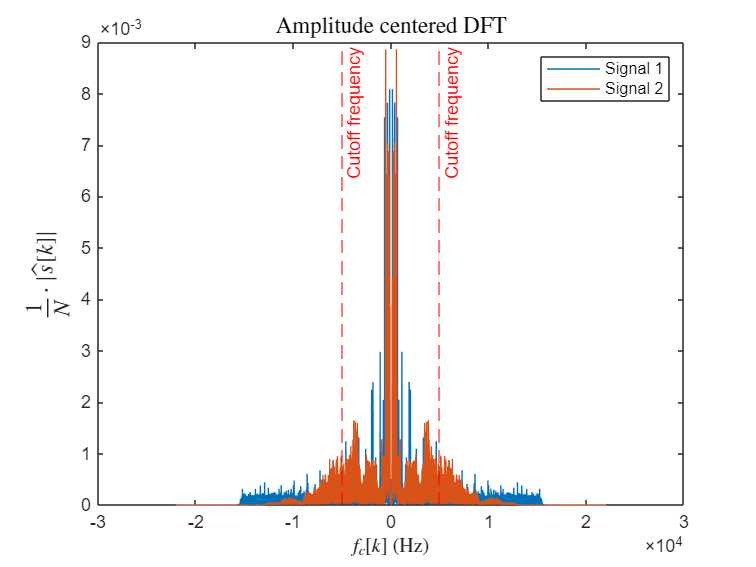

[FFT_signal_1, FFT_signal_2] = FFT(signal_1, signal_2);
shifted_FFT_signal_1_magnitude = 1/N*abs([FFT_signal_1(N_half+1:end), FFT_signal_1(1:N_half)]);    % Centering the FFT
shifted_FFT_signal_2_magnitude = 1/N*abs([FFT_signal_2(N_half+1:end), FFT_signal_2(1:N_half)]);    % Centering the FFT

k=1:N;                                                             
f=(k-1)*(1/(N*ts));                                                 
f_c=f-((N-mod(N,2))/2)*(1/(N*ts));                                                             % Frequency axis

figure
plot(f_c,shifted_FFT_signal_1_magnitude) 
hold on
plot(f_c,shifted_FFT_signal_2_magnitude) 
xline(-cutoff_f,LineStyle="--",Color='red',Label='Cutoff frequency')
xline(cutoff_f,LineStyle="--",Color='red',Label='Cutoff frequency')
hold off
title('Amplitude centered DFT','Interpreter','Latex', 'FontSize', 13)
xlabel('$f_c[k]$ (Hz)','Interpreter','Latex')
ylabel('$\frac{1}{N} \cdot |\hat{s}[k]|$','Interpreter','Latex', 'FontSize', 13)
legend('Signal 1','Signal 2')

 
volume = 0.5; % Lautstärke zwischen 0 und 1
signal_1_reduced = signal_1 * volume;
sound(signal_1_reduced, fs)

## LowPassFilter

run('LowPassFilter.mlx');

No alaising due to cutoff frequenzy 5000Hz < sampling frequenzy/2 22050Hz


sinc requires one of the following:
  Signal Processing Toolbox
  Symbolic Math Toolbox

Error in LowPassFilter (line 9)
x_k = w_c_norm*sinc(w_c_norm*(k-(n-1)/2));

Error in run (<a hre

 
volume = 0.5; % Lautstärke zwischen 0 und 1
signal_1_reduced = h1 * volume;
sound(signal_1_reduced, fs)

## DFT

run('DFT.mlx');

## FFT recursiv

run('FFTrecursive.mlx');

## FFT iterativ

run('FFTiterativ.mlx');

## Time difference

disp(['Calculation of DFT ' num2str(time_DFT)])
disp(['Calculation of DFT ' num2str(time_FFT_recursiv)])
disp(['Calculation of DFT ' num2str(time_FFT_iterativ)])

## Computation effort

Number of multiplications

cost_DFT = [length(h1)^2, length(h2)^2]
cost_FFT_recursive = [length(h1)/2*log2(length(h1)), length(h2)/2*log2(length(h2))]
cost_FFT_iterativ = [length(h1)/2*log2(length(h1)), length(h2)/2*log2(length(h2))]

## LowpassfilterFFT

run('LowPassFilterFFT.mlx')

## Modulation / Demodulation

run('Modulation_Demodulation.mlx')


clear all; % Clear all variables from the workspace to start fresh

%% Signal Creation
use_audio = true; % Flag to determine if audio files will be used
export_img = false; % Flag to determine if images/plots will be exported

if use_audio
    % Load the audio signals from files
    [signal_1_stereo, ~] = audioread('super-mario_kurz.mp3'); % Load audio file for signal 1
    [signal_2_stereo, fs] = audioread('fake-news.mp3');       % Load audio file for signal 2
    
    % Extract the left channel (mono) from stereo signals
    signal_1 = signal_1_stereo(:,1)'; % Convert to row vector
    signal_2 = signal_2_stereo(:,1)'; % Convert to row vector
    
    % Adjust signal lengths to the nearest power of 2 for FFT optimization
    N = length(signal_1); % Get original length of signal 1
    N_log2 = 2^floor(log2(N)); % Compute the largest power of 2 less than or equal to N

    % Trim both signals to the adjusted length
    signal_1 = signal_1(1:N_log2); 
    signal_2 = signal_2(1:N_log2);

    % Update parameters based on adjusted signal length
    N = length(signal_1); % Update length after trimming
    N_log2 = log2(N);     % Update base-2 logarithm of N
    N_half = N / 2;       % Half of the signal length (used for FFT visualization)
    t = (0:N-1) / fs;     % Create a time axis for plotting
    ts = 1 / fs;          % Sampling period (inverse of sampling frequency)
    cutoff_f = 5000;      % Set the cutoff frequency for filtering (in Hz)
else
    % Use synthetic square wave signals if audio files are not used
    fs = 1000; % Sampling frequency (Hz)
    ts = 1/fs; % Sampling period (s)
    duration = 2^10 / 1000; % Duration of the signal in seconds
    t = 0:1/fs:duration-ts; % Create a time axis
    freq_sinus = 100; % Frequency of the first square wave (Hz)
    freq_rechteck = 150; % Frequency of the second square wave (Hz)
    signal_1 = square(2 * pi * freq_sinus * t); % Generate square wave for signal 1
    signal_2 = square(2 * pi * freq_rechteck * t); % Generate square wave for signal 2
    N = length(signal_1); % Length of synthetic signals
    cutoff_f = 490; % Set cutoff frequency for synthetic signals
end

%% Plot the Initial Signals
figure(); % Create a new figure for plotting
tiledlayout(2,1); % Divide the figure into a 2x1 grid for two plots

% Plot Signal 1
nexttile;
plot(t, signal_1); % Plot signal 1 against time
title('Signal 1', 'Interpreter', 'Latex'); % Title of the plot
xlabel('$t$(s)', 'Interpreter', 'Latex', 'FontSize', 13); % X-axis label
ylabel('$s[t]$', 'Interpreter', 'Latex', 'FontSize', 13); % Y-axis label
xlim([0 max(t)]); % Set X-axis limits to the signal's duration
ylim([min(signal_1)*1.1 max(signal_1)*1.1]); % Set Y-axis limits with some margin

% Plot Signal 2
nexttile;
plot(t, signal_2); % Plot signal 2 against time
title('Signal 2', 'Interpreter', 'Latex'); % Title of the plot
xlabel('$t$(s)', 'Interpreter', 'Latex', 'FontSize', 13); % X-axis label
ylabel('$s[t]$', 'Interpreter', 'Latex', 'FontSize', 13); % Y-axis label
xlim([0 max(t)]); % Set X-axis limits to the signal's duration
ylim([min(signal_2)*1.1 max(signal_2)*1.1]); % Set Y-axis limits with some margin

%% Compute FFT and Center it
[FFT_signal_1, FFT_signal_2] = FFT(signal_1, signal_2); % Call FFT function to compute the FFT of both signals

% Compute centered FFT magnitudes
shifted_FFT_signal_1_magnitude = 1/N * abs([FFT_signal_1(N_half+1:end), FFT_signal_1(1:N_half)]); % Rearrange FFT output for visualization
shifted_FFT_signal_2_magnitude = 1/N * abs([FFT_signal_2(N_half+1:end), FFT_signal_2(1:N_half)]); % Rearrange FFT output for visualization

% Create frequency axis for plotting
k = 1:N; % Create an index vector
f = (k-1) * (1 / (N * ts)); % Compute frequency in Hz
f_c = f - ((N - mod(N,2)) / 2) * (1 / (N * ts)); % Center the frequency axis

%% Plot Centered FFT Magnitude
figure; % Create a new figure for FFT plots
plot(f_c, shifted_FFT_signal_1_magnitude); % Plot centered FFT magnitude for signal 1
hold on;
plot(f_c, shifted_FFT_signal_2_magnitude); % Plot centered FFT magnitude for signal 2
xline(-cutoff_f, 'LineStyle', "--", 'Color', 'red', 'Label', 'Cutoff frequency'); % Mark negative cutoff frequency
xline(cutoff_f, 'LineStyle', "--", 'Color', 'red', 'Label', 'Cutoff frequency'); % Mark positive cutoff frequency
hold off;
title('Amplitude Centered DFT', 'Interpreter', 'Latex', 'FontSize', 13); % Title for FFT plot
xlabel('$f_c[k]$ (Hz)', 'Interpreter', 'Latex'); % X-axis label
ylabel('$\frac{1}{N} \cdot |\hat{s}[k]|$', 'Interpreter', 'Latex', 'FontSize', 13); % Y-axis label
legend('Signal 1', 'Signal 2'); % Add legend for signals

%% Play Audio Signal
volume = 0.5; % Set volume for playback (50% of original volume)
signal_1_reduced = signal_1 * volume; % Reduce the amplitude of signal 1
sound(signal_1_reduced, fs); % Play signal 1 at the sampling rate

%% LowPassFilter Processing
run('LowPassFilter.mlx'); % Run the script for low-pass filtering

% Play the filtered signal
volume = 0.5; % Set volume for playback (50% of original volume)
signal_1_reduced = h1 * volume; % Reduce the amplitude of the filtered signal
sound(signal_1_reduced, fs); % Play the filtered signal

%% DFT and FFT Comparisons
run('DFT.mlx'); % Compute DFT
run('FFTrecursive.mlx'); % Compute recursive FFT
run('FFTiterativ.mlx'); % Compute iterative FFT

% Display Time Differences for Each Method
disp(['Calculation of DFT ' num2str(time_DFT)]);
disp(['Calculation of FFT Recursive ' num2str(time_FFT_recursiv)]);
disp(['Calculation of FFT Iterative ' num2str(time_FFT_iterativ)]);

% Compute Multiplication Costs for Each Method
cost_DFT = [length(h1)^2, length(h2)^2]; % DFT computational cost
cost_FFT_recursive = [length(h1)/2*log2(length(h1)), length(h2)/2*log2(length(h2))]; % Recursive FFT cost
cost_FFT_iterativ = [length(h1)/2*log2(length(h1)), length(h2)/2*log2(length(h2))]; % Iterative FFT cost

%% Fast Convolution with FFT
run('LowPassFilterFFT.mlx'); % Run low-pass filtering with FFT

%% Modulation and Demodulation
run('Modulation_Demodulation.mlx'); % Run modulation and demodulation script
